## Zestaw 4

Ad 1

    Generowanie losowego digrafu zespołu(n, p)

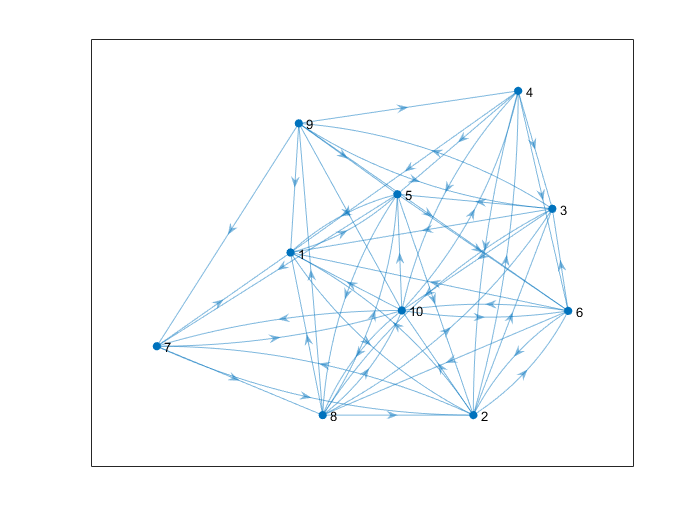

clear; close all; clc;
n = 10;
p = 0.5;
digraph1 = genRandDigraph(n, p);
% A = ones(n) - eye(n);
% digraph1 = Digraph(A);

plot(digraph1);

digraph1.getAdjacencyMatrix()

ans =      0     1     0     0     1     0     0     0     0     0
     1     0     1     1     0     1     1     0     0     1
     1     0     0     0     1     0     0     1     1     1
     1     1     1     0     1     1     0     0     0     1
     1     1     0     0     0     1     1     1     0     0
     1     1     1     0     0     0     0     1     0     1
     1     1     0     0     0     0     0     1     0     1
     1     1     1     0     1     0     0     0     1     1
     1     0     1     1     1     1     1     0     0     1
     1     0     0     1     1     1     1     1     0     0


Ad 2

    Wyznaczanie spójnych składowych algorytmem Kosaraju

comp = kosaraju(digraph1)

comp =      1     1     1     1     1     1     1     1     1     1


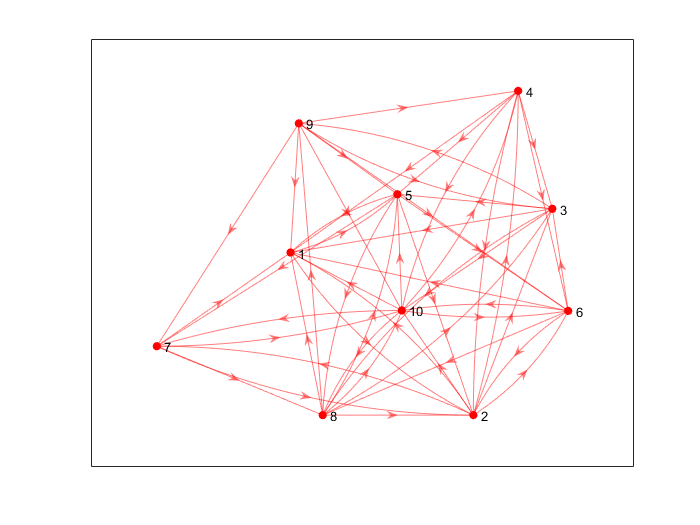

h = plot(digraph1);
nodes = digraph1.Nodes;
ncomp1 = nodes(comp==1);
for i=1:length(ncomp1)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp1(i));
    highlight(h,ncomp1(i),intersect(nbors, ncomp1),'EdgeColor','r');
end
highlight(h,ncomp1,'NodeColor','r');

highlight(h,nodes(comp==2),'NodeColor','g');
ncomp2 = nodes(comp==2);
for i=1:length(ncomp2)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp2(i));
    highlight(h,ncomp2(i),intersect(nbors, ncomp2),'EdgeColor','g');
end
highlight(h,nodes(comp==3),'NodeColor','m');
ncomp3 = nodes(comp==3);
for i=1:length(ncomp3)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp3(i));
    highlight(h,ncomp3(i),intersect(nbors, ncomp3),'EdgeColor','m');
end

Ad 3 i 4

    Algorytm Bellmana-Forda oraz Johnsona

if max(comp)==1
    noEdges = length(digraph1.Edges(1,:));
    weights = randi(10,[1, noEdges]);

Aby uniknąć ujemnych cyklów liczba krawędzi z wagami mniejszymi jest znacząco mniejsza od liczby krawędzi z wagami dodatnimi

    noEdgesMinus= round(sqrt(n));
    for i=1:noEdgesMinus
        weights(randi(noEdges)) = -randi(5);
    end
    digraph1.Edges = [digraph1.Edges; weights];
    h = plot(digraph1.getDigraph(),'EdgeLabel',weights);
    [D, P] = johnson(digraph1)
    

Zaznaczanie wybranej ścieżki

D =      0     1     7     1     4     5     6     7    12     5
     0     0     6     0     3     4     5     6    11     4
     3     4     0     3     3     7     8     6    10     7
     2     3     6     0     3     4     7     6    11     6
     0     1     7     1     0     5     5     3     8     5
    -2    -1     4    -2     1     0     3     4     9     2
    -5    -4     2    -4    -1     0     0     2     7     0
    -2    -2     4    -2     1     2     3     0     5     2
    -4    -3     3    -3     0     1     1     3     0     1
    -4    -3     2    -4    -1     0     1     2     7     0


P =      0     1     4    10     4     4    10     5     8     2
     7     0     4    10     4     4    10     5     8     2
     3     8     0    10     3     4     5     5     3     3
     7     1     4     0     4     4    10     5     8     4
     7     8     4    10     0     4     5     5     8     2
     7     1     4    10     4     0    10     6     8     6
     7     1     4    10     4     4     0     5     8     2
     7     8     4    10     8     4    10     0     8     2
     7     1     4    10     4     4     9     5     0     2
     7     1     4    10     4     4    10     5     8     0


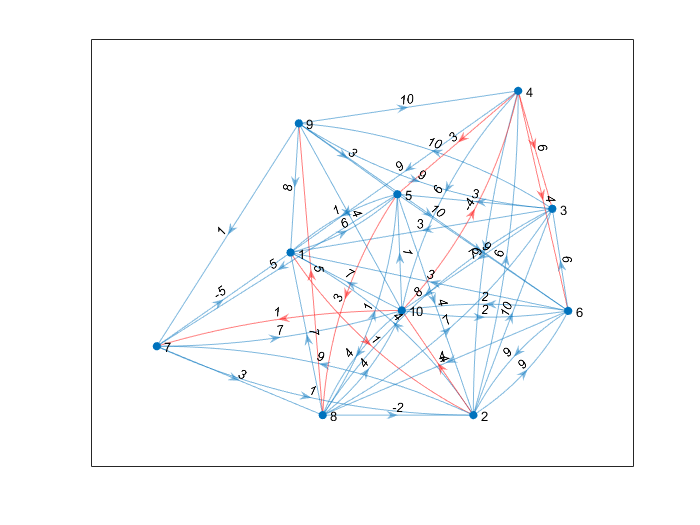

    noPath = 1;
    path = P(noPath, :);
    for i=1:n
        if i==noPath
            continue;
        end
       highlight(h,path(i),i,'EdgeColor','r'); 
    end
else
    error("Digraf nie jest silnie spójny! Proszę spróbować inny")
end